# Chapter 11

*Original author: Allen Downey (2017)*

*Author: Zachary del Rosario (2020)*

% Set the random state
rng(101)

% NOTE: If this cell is successful, it produces no output

## SIR Implementation

tab_system = fcn_make_system(1/3, 1/4)

tab_system = 1×5 table
              init              t0    tf     beta      gamma
       S          I        R                                
    ________________________    __    __    _______    _____

    0.98889    0.011111    0    0     98    0.33333    0.25 


tab_state = fcn_update(tab_system.init, 0, tab_system)

tab_state = 1×3 table
       S          I            R    
    _______    ________    _________

    0.98523    0.011996    0.0027778


tab_record = fcn_simulate(tab_system, @fcn_update)

tab_record = 100×4 table
       S          I            R          t   
    _______    ________    _________    ______

    0.98523    0.011996    0.0027778         0
    0.98129    0.012936    0.0057767    0.9899
    0.97706    0.013934    0.0090109    1.9798
    0.97252    0.014988     0.012494    2.9697
    0.96766      0.0161     0.016241    3.9596
    0.96247    0.017268     0.020266    4.9495
    0.95693    0.018491     0.024584    5.9394
    0.95103    0.019767     0.029206    6.9293
    0.94476    0.021091     0.034148    7.9192
    0.93812     0.02246     0.039421    8.9091
     0.9311    0.023869     0.045036     9.899
    0.92369     0.02531     0.051003    10.889
    0.91589    0.026775      0.05733    11.879
    0.90772    0.028256     0.064024    12.869
    0.89917    0.029741     0.071088    13.859
    0.89026     0.03122     0.078523   

### Plot

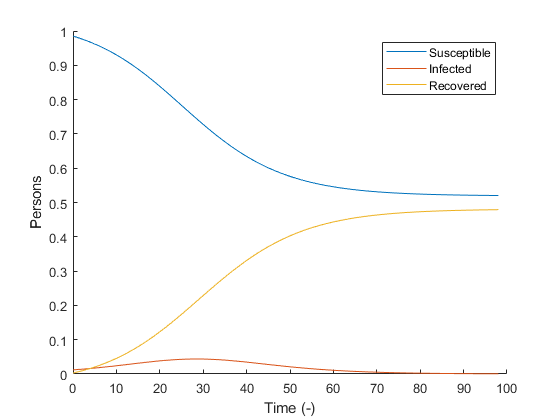

plt_record(tab_record);